# Setup Pluto

clear; close all; clc;

rx = sdrrx('Pluto');
tx = sdrtx('Pluto');

## Transmitter

% --- Konfigurer senderen ---
tx.CenterFrequency = 800e6;       % 800 MHz senterfrekvens
tx.Gain = 0;                    % Senderforsterkning i dB
tx.ShowAdvancedProperties = true;  % Vis avanserte parametere
tx.FrequencyCorrection = 0;        % Juster frekvenskorreksjon hvis nødvendig

## Receiver

rx.CenterFrequency = 800e6;       % 800 MHz mottaksfrekvens
rx.GainSource = 'AGC Slow Attack';% Automatisk gain-kontroll
rx.OutputDataType = 'double';     % Dataformat
rx.SamplesPerFrame = 1e5;         % Antall samples per ramme

## OQPSK

% --- OQPSK-parameteroppsett ---
symbolRate = 100e3;   % Sett symbolhastighet til 100 ksym/s (tilpass for din applikasjon)
sps = 8;            % Samples per symbol (må være høy nok for OQPSK)
tx.BasebandSampleRate = symbolRate * sps;  % Juster samplingsfrekvensen basert på symbolhastighet
rx.BasebandSampleRate = symbolRate * sps;      % Match senderens basebånd samplingsrate

modulator = comm.OQPSKModulator('BitInput', true);
demodulator = comm.OQPSKDemodulator('BitOutput',true);

## Root Raised Cosine Filter

span = 4;                 % Filter span (number of symbols)
decimation=sps/2;
rolloff = 0.5;               % Rolloff factor

txFilter = comm.RaisedCosineTransmitFilter( ...
    'Shape','Square root',...
    'RolloffFactor', rolloff, ...
    'FilterSpanInSymbols', span, ...
    'OutputSamplesPerSymbol', sps);

rxFilter = comm.RaisedCosineReceiveFilter( ...
    'Shape','Square root',...
    'RolloffFactor', rolloff, ...
    'FilterSpanInSymbols', span, ...
    'InputSamplesPerSymbol', sps, ...
    'DecimationFactor', decimation);

## Synchronization

symbolSync = comm.SymbolSynchronizer(...
    'SamplesPerSymbol', sps/decimation, ...
    'Modulation','OQPSK', ...
    'TimingErrorDetector','Gardner (non-data-aided)');

CFC = comm.CoarseFrequencyCompensator( ...
    'Modulation', 'OQPSK', ...
    'SampleRate', 1e5, ...
    'FrequencyResolution', 1e4);  % Higher resolution for better accuracy

FFC = comm.CarrierSynchronizer( ...
    'Modulation', 'OQPSK', ...
    'SamplesPerSymbol', 2, ...
    'DampingFactor', 0.707, ...           % Critically damped for faster response
    'NormalizedLoopBandwidth', 0.1);   

# Transmit & Receive

## Tx

% Generer en tilfeldig binær strøm
txData=randi([0 1], 1000, 1);

txSignal = modulator(txData); 
txSignalFiltered = txFilter(txSignal);

% Send signalet
tx.transmitRepeat(txSignalFiltered);

## Establishing connection to hardware. This process can take several seconds.
## Waveform transmission has started successfully and will repeat indefinitely. 
## Call the release method to stop the transmission.


disp('Sender OQPSK-signal...');

Sender OQPSK-signal...


## Rx

% Start mottak
disp('Lytter etter OQPSK-signal...');

Lytter etter OQPSK-signal...


rxSignal = rx();

## Establishing connection to hardware. This process can take several seconds.



% Filtrer
rxSignalFiltered = rxFilter(rxSignal);

% Symbol Sync
rx_I_sync = real(symbolSync(real(rxSignalFiltered)));
rx_Q_sync = real(symbolSync(imag(rxSignalFiltered)));
minLength = min(length(rx_I_sync), length(rx_Q_sync));
rx_I_sync = rx_I_sync(1:minLength);
rx_Q_sync = rx_Q_sync(1:minLength);
rxSignalSynced=rx_I_sync + 1j*rx_Q_sync;

% Carrier Sync
rxSignalCoarse=CFC(rxSignalSynced);
rxSignalFine=FFC(rxSignalCoarse);

% Frame Sync
rxSignalFinale=rxSignalFine;
rxData=demodulator(rxSignalFinale);

# Tidsserie

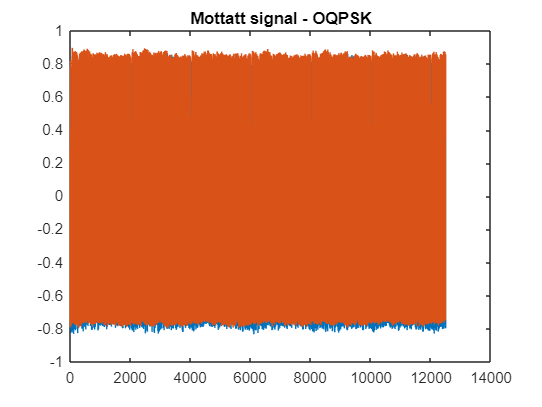

% Plott signalet for analyse
figure; 
plot(real(rxSignalFinale));
hold on;
plot(imag(rxSignalFinale));
title('Mottatt signal - OQPSK');

# PSD

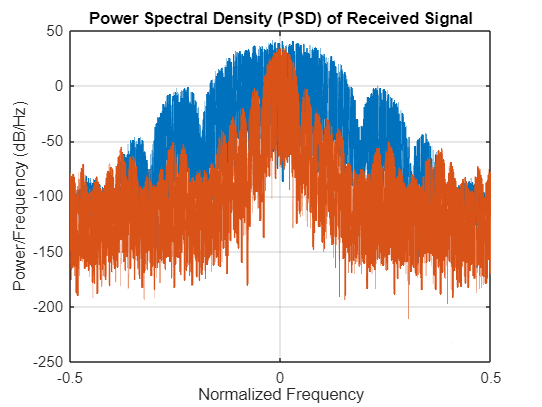

figure;
[psdRaw, psdFreq] = periodogram(rxSignal, [], [], 1, 'centered');
[psdFiltered, psdFreqFilt] = periodogram(rxSignalFiltered, [], [], 1, 'centered');
plot(psdFreqFilt, mag2db(psdFiltered), 'LineWidth', 1.5,'DisplayName',"Filtered");
hold on;
plot(psdFreq, mag2db(psdRaw), 'LineWidth', 1.5,"DisplayName","Raw");
title('Power Spectral Density (PSD) of Received Signal');
xlabel('Normalized Frequency');
ylabel('Power/Frequency (dB/Hz)');
grid on;

# Constellation

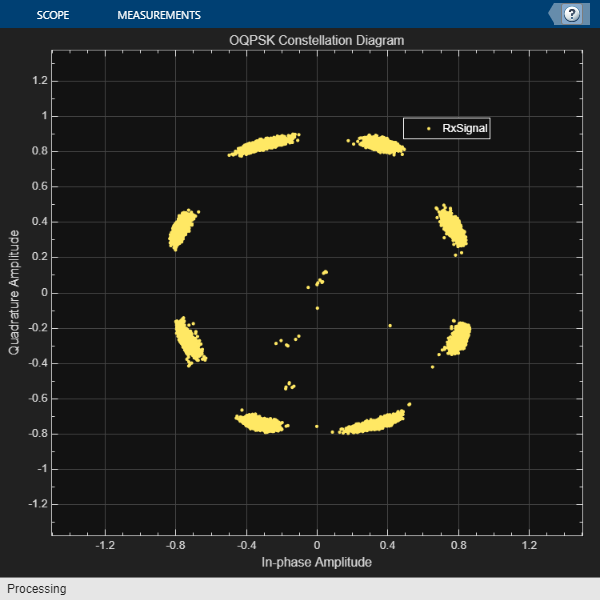

% Create a Constellation Diagram object
constDiagram = comm.ConstellationDiagram( ...
    'ReferenceConstellation', 0, ...
    'NumInputPorts', 1, ...
    'ShowLegend', true, ...
    'Title', 'OQPSK Constellation Diagram', ...
    'ChannelNames', {'RxSignal', 'TxSignal'});

% Visualize rxSignal and txSignal in the constellation diagram
constDiagram(rxSignalFinale);

# Eye-Diagram

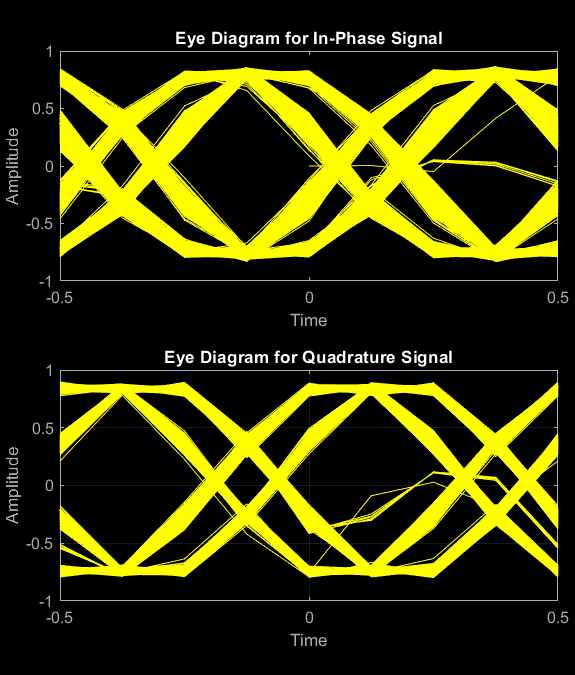

figure;
eyediagram(rxSignalFinale, sps);
xlabel('Time');
ylabel('Amplitude');
grid on;